clearvars; close all
% Path to the project folder
chdir('D:\Profile\qse\files\projects\sijia_sulphurization');
% Add source file directory
addpath(genpath('scr'));

## Import

% X-band data: sample 4 in a Q-band tube measured in the X-band high-Q cavity
load('data/processed/gm20230720_sample4.mat');
cwX = cw; % Mw power 1.1 mW
% Load Qband data
load('data/processed/gm20230622_sample4_Qband_mwpw.mat');
cwQ = cw(5); % Mw power 0.2 mW

## Fit

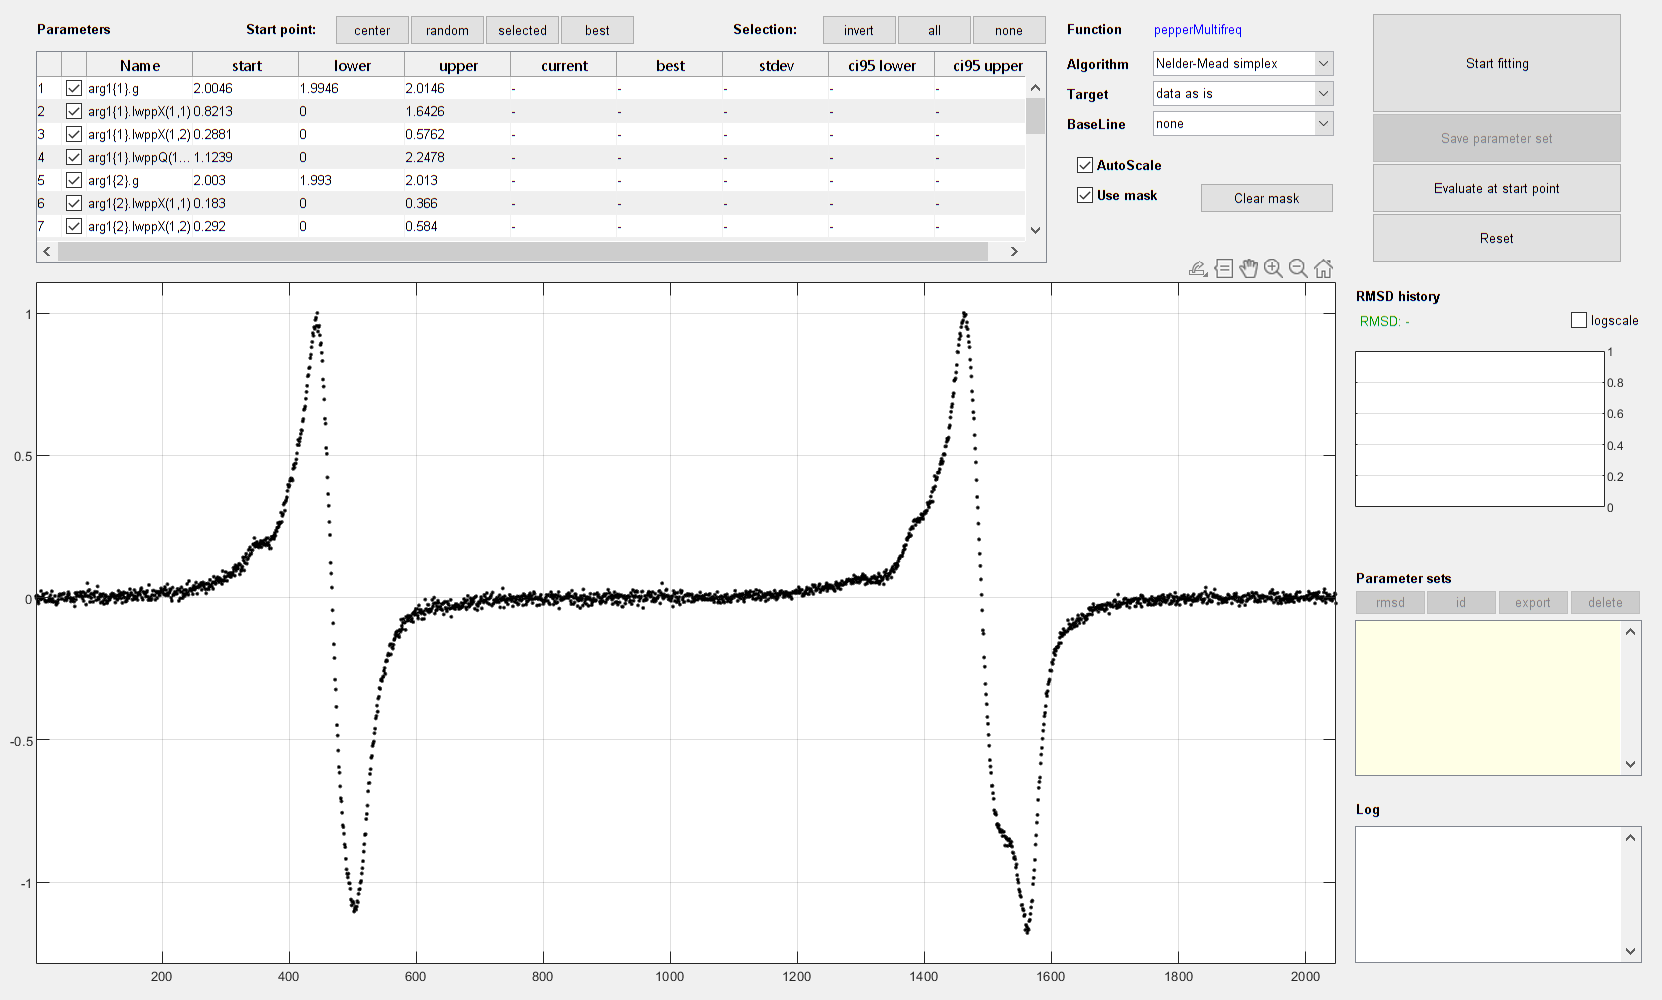

Sys0 = struct('g', 2.0046, ...
    'lwppX', [0.8213 0.2881], ...
    'lwppQ', [0. 1.1239]);
Sys1 = struct('g', 2.003, ...
    'lwppX', [0.1830 0.2920], ...
    'lwppQ', [0.8397 0.], ...
    'weightX', 2.5e-5, ...
    'weightQ', 2.5e-5);
Sys2 = struct('g', 2.0065, ...
    'lwppX', [0.3656 0.2366], ...
    'lwppQ', [0.0102 1.4412], ...
    'weightX', 0.3, ...
    'weightQ', 1e-4);
Sys3 = struct('g', 2.009, ...
    'lwppX', [0.3656 0.2366], ...
    'lwppQ', [0.0102 1.4412], ...
    'weightX', 0.3, ...
    'weightQ', 1e-4);

Vary0 = struct('g', .01, ...
    'lwppX', Sys0.lwppX, ...
    'lwppQ', Sys0.lwppQ);
Vary1 = struct('g', .01, ...
    'lwppX', Sys1.lwppX, ...
    'lwppQ', Sys1.lwppQ, ...
    'weightX', Sys1.weightX, ...
    'weightQ', Sys1.weightQ);
Vary2 = struct('g', .01, ...
    'lwppX', Sys2.lwppX, ...
    'lwppQ', Sys2.lwppQ, ...
    'weightX', Sys2.weightX, ...
    'weightQ', Sys2.weightQ);
Vary2 = struct('g', .01, ...
    'lwppX', Sys3.lwppX, ...
    'lwppQ', Sys3.lwppQ, ...
    'weightX', Sys3.weightX, ...
    'weightQ', Sys3.weightQ);

% Prepare x and y arrays for multifrequency
xdataX = cwX.x;
ydataX = cwX.y;
xdataQ = cwQ.x;
ydataQ = cwQ.y;

% Rescale for better display during simulation
yX = ydataX/max(ydataX); 
yQ = ydataQ/max(ydataQ);

% Store for rescaling within custom simulation function
Sys0.dataX = yX;
Sys0.dataQ = yQ;

% Exp
Exp.CenterSweepX = [mean(xdataX) (max(xdataX) - min(xdataX))];
Exp.CenterSweepQ = [mean(xdataQ) (max(xdataQ) - min(xdataQ))];
Exp.nPointsX = numel(xdataX);
Exp.nPointsQ = numel(xdataQ);
Exp.mwFreqX = cwX.Params.MWFQ*1e-9;
Exp.mwFreqQ = cwQ.Params.MWFQ*1e-9;

SimOpt.Verbosity = 0;
SimOpt.Output = 'summed';

% totPoints = Exp.nPointsX + Exp.nPointsQ;
% FitOpt.mask = (1:totPoints < 195) | ...
%     ((1:totPoints > 378) & (1:totPoints < 195 + Exp.nPointsX)) | ...
%     (1:totPoints > 378 + Exp.nPointsX);
FitOpt.BaseLine = [];

% Combine datasets
y = [yX', yQ'];

Sys = {Sys0, Sys1, Sys2, Sys3};
SysVary = {Vary0, Vary1, Vary2, Sys3};

esfit(y, @pepperMultifreq, {Sys, Exp, SimOpt}, {SysVary}, FitOpt);

### Immediately save the fit

Dir.SPath = 'data/processed/gm_fitMultifreq.mat';
% Title = 'Fit multifreq sample 4: X-band 20230720 long accum and Q-band 20230622 mwpw 18dB';
% save(Dir.SPath, 'Fit', 'Title');

### Simulate separate components

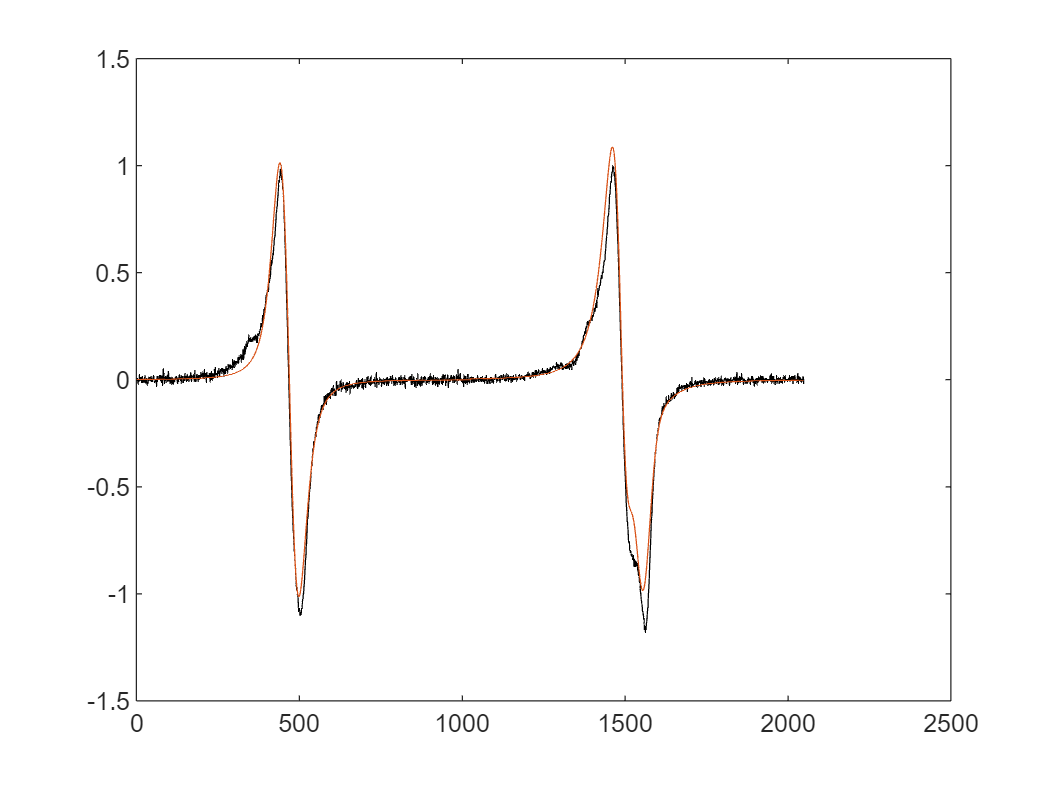

Dir.LPath = 'data/processed/gm_fitMultifreq.mat';
load(Dir.LPath)
load("ColorsPlot.mat")

[Sys, Exp, SimOpt] = Fit.argsfit{:};
SimOpt.Output = 'separate';

yFitX = runPepperFreqBand(Sys, Exp, SimOpt, 'X');
[~, scaleX] = rescaledata(yFitX(1, :) + yFitX(2, :), Fit.fit(1:Exp.nPointsX), 'lsq');
yFitQ = runPepperFreqBand(Sys, Exp, SimOpt, 'Q');
[~, scaleQ] = rescaledata(yFitQ(1, :) + yFitQ(2, :), Fit.fit(Exp.nPointsX + 1:Exp.nPointsX + Exp.nPointsQ), 'lsq');
Fit.yFit = {scaleX*yFitX, scaleQ*yFitQ};

% [xdataX', xdataQ']
figure()
plot(1:numel(Fit.fit), y, 'Color', PlotColors(1), 'DisplayName', 'Fit')
hold on
plot(1:numel(Fit.fit), Fit.fit, 'Color', PlotColors(2), 'DisplayName', 'Fit')

% hold on
% for ib = 1:numel(Fit.yFit) % ib stands for ith frequency band
%     for ic = 1:numel(Fit.yFit{ib}(:, 1)) % ic stands for ith component
%         if ib == 1
%             xx = 1:Exp.nPointsX;
%         elseif ib == 2
%             xx = Exp.nPointsX + 1:Exp.nPointsX + Exp.nPointsQ;
%         end
%         plot(xx, Fit.yFit{ib}(ic, :), 'Color',  PlotColors(3),  'DisplayName', 'Spin 2.0046')
%     end
% end
% plot(1025:2048, 20*sum(yFit), 'Color',  PlotColors(4),  'DisplayName', 'Spin 2.0046')
% plot(1025:2048, yFit(2, :), 'Color',  PlotColors(4), 'DisplayName', 'Spin 2.003')
% Fit.yFit0 = yFit(1, :);
% Fit.yFit1 = yFit(2, :);

% Title = '2023-06-22 sample 4 Qband mwpw 18dB fit';
% save(Dir.SPath, 'Fit', 'Title');

Sys1f = struct('g', 2.0043, ...
    'lwpp', [0.3068 0.2281]);
Sys2f = struct('g', 2.0058, ...
    'lwpp', [0.1677 0.3492], ...
    'weight', 1.7510);
Sys4f = struct('g', 2.0077, ...
    'lwpp', [0.2251 0.8298], ...
    'weight', 2.0587);

figure()
plot(cw(ICW).x, cw(ICW).y)
hold on
Opt.Output = 'separate';
plot(cw(ICW).x, fit1.scale*pepper({Sys1f, Sys2f, Sys4f}, Exp, Opt))

xx = cwX.x(1:20:numel(cwX.x));
yy = cwX.y(1:20:numel(cwX.y));
figure()
plot(cwX.x, cwX.y, xx, yy)

test = pepperMultifreq(Sys, Exp, SimOpt);


function yFit = pepperMultifreq(Sys, Exp, SimOpt)
    yFitX = runPepperFreqBand(Sys, Exp, SimOpt, 'X');
    % yFitX = yFitX/max(yFitX); 

    yFitQ = runPepperFreqBand(Sys, Exp, SimOpt, 'Q');
    % yFitQ = yFitQ/max(yFitQ);

    % rescale each spectrum individually here since, internally, esfit will
    % rescale the concatenated output yFit
    yXref = Sys{1}.dataX;
    yQref = Sys{1}.dataQ;
    
    yFit = [rescaledata(yFitX,yXref,'lsq'), rescaledata(yFitQ,yQref,'lsq')];
end

function yFit = runPepperFreqBand(Sys, Exp, SimOpt, freqBand)
    nSys = numel(Sys);

    for isys = 1:nSys
        Fields = fieldnames(Sys{isys});
        for ii = 1:numel(Fields)
            if endsWith(Fields{ii}, freqBand)
                Field_ = Fields{ii}(1:end - 1);
                Sys{isys}.(Field_) = Sys{isys}.(Fields{ii});
            end
        end
    end

    Fields = fieldnames(Exp);
    for ii = 1:numel(Fields)
        if endsWith(Fields{ii}, freqBand)
            Field_ = Fields{ii}(1:end - 1);
            Exp.(Field_) = Exp.(Fields{ii});
        end
    end
    
    yFit = pepper(Sys, Exp, SimOpt);

    % if strcmp(SimOpt.Output, 'summed')
    %     yX = y/max(y);
    %     yX = rescaledata(yX,yXref,'lsq');
    % elseif strcmp(SimOpt.Output, 'separate')
    %     yX = y;
    %     % [~, scaleFactor] = rescaledata(yX(1, :) + yX(2, :),yXref,'lsq')
    %     %for isys = 1:nSys
    %     %    yX(isys, :) = scaleFactor*yX(isys, :)/max(yX(isys, :));
    %     %end
    % end
end